% jan 2020

% ex 3

## COMPLETE EXAMPLE

% quintic polynomial

## S(tau)

syms tau real
syms a b c d e f real
syms qin qfin real
syms vin vfin real
syms ain afin real
syms T real positive
syms Dq real

Dq = qfin-qin

$$Dq = \mathrm{qfin}-\mathrm{qin}$$

q_tau = a*tau^5 + b*tau^4 + c*tau^3 + d*tau^2 + e*tau + f

$$q\_tau = a\,\tau^{5}+b\,\tau^{4}+c\,\tau^{3}+d\,\tau^{2}+e\,\tau +f$$


%compute coefficients 
q_tau_0 = simplify(subs(q_tau, {tau}, {0}));
eq_1 = q_tau_0 == qin

$$eq\_1 = f=\mathrm{qin}$$


q_tau_1 = simplify(subs(q_tau, {tau}, {1}));
eq_2 = q_tau_1 == qfin

$$eq\_2 = a+b+c+d+e+f=\mathrm{qfin}$$


q_tau_diff = diff(q_tau, {tau});
q_tau_diff_0 = subs(q_tau_diff, {tau}, {0});
eq_3 = q_tau_diff_0 == vin*T

$$eq\_3 = e=T\,\mathrm{vin}$$


q_tau_diff_1 = subs(q_tau_diff, {tau}, {1});
eq_4 = q_tau_diff_1 == vfin*T

$$eq\_4 = 5\,a+4\,b+3\,c+2\,d+e=T\,\mathrm{vfin}$$


q_tau_dd = diff(q_tau_diff, {tau});
q_tau_dd_0 = subs(q_tau_dd, {tau}, {0});
eq_5 = q_tau_dd_0 == ain*T^2

$$eq\_5 = 2\,d=T^{2}\,\mathrm{ain}$$


q_tau_dd_1 = subs(q_tau_dd, {tau}, {1});
eq_6 = q_tau_dd_1 == afin*T^2

$$eq\_6 = 20\,a+12\,b+6\,c+2\,d=T^{2}\,\mathrm{afin}$$


sol = solve([eq_1, eq_2, eq_3, eq_4, eq_5, eq_6], [a,b,c,d,e,f]);
a = simplify(sol.a)

$$a = 6\,\mathrm{qfin}-6\,\mathrm{qin}-3\,T\,\mathrm{vfin}-3\,T\,\mathrm{vin}+\frac{T^{2}\,\mathrm{afin}}{2}-\frac{T^{2}\,\mathrm{ain}}{2}$$

b = simplify(sol.b)

$$b = 15\,\mathrm{qin}-15\,\mathrm{qfin}+7\,T\,\mathrm{vfin}+8\,T\,\mathrm{vin}-T^{2}\,\mathrm{afin}+\frac{3\,T^{2}\,\mathrm{ain}}{2}$$

c = simplify(sol.c)

$$c = 10\,\mathrm{qfin}-10\,\mathrm{qin}-4\,T\,\mathrm{vfin}-6\,T\,\mathrm{vin}+\frac{T^{2}\,\mathrm{afin}}{2}-\frac{3\,T^{2}\,\mathrm{ain}}{2}$$

d = simplify(sol.d)

$$d = \frac{T^{2}\,\mathrm{ain}}{2}$$

e = simplify(sol.e)

$$e = T\,\mathrm{vin}$$

f = simplify(sol.f)

$$f = \mathrm{qin}$$


%input
qin = 0

qin = 0

qfin = 1

qfin = 1


vin = 0.5

vin = 0.5000

vfin=0

vfin = 0


ain=0

ain = 0

afin=0

afin = 0

T = 2

T = 2

% compute maximum value (acc, vel)
a = simplify(subs(a))

$$a = 3$$

b = simplify(subs(b))

$$b = -7$$

c = simplify(subs(c))

$$c = 4$$

d = simplify(subs(d))

$$d = 0$$

e = simplify(subs(e))

$$e = 1$$

f = simplify(subs(f))

$$f = 0$$


syms t real
q_t = simplify(subs(q_tau, {tau}, {t/T}))

$$q\_t = \frac{a\,t^{5}}{32}+\frac{b\,t^{4}}{16}+\frac{c\,t^{3}}{8}+\frac{d\,t^{2}}{4}+\frac{e\,t}{2}+f$$

q_t_dot = diff(q_t, {t})

$$q\_t\_dot = \frac{5\,a\,t^{4}}{32}+\frac{b\,t^{3}}{4}+\frac{3\,c\,t^{2}}{8}+\frac{d\,t}{2}+\frac{e}{2}$$

q_t_dot_dot = diff(q_t_dot, {t})

$$q\_t\_dot\_dot = \frac{5\,a\,t^{3}}{8}+\frac{3\,b\,t^{2}}{4}+\frac{3\,c\,t}{4}+\frac{d}{2}$$


q_t_1 = subs(q_t)

$$q\_t\_1 = \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2}$$

q_t_dot_1 = subs(q_t_dot)

$$q\_t\_dot\_1 = \frac{15\,t^{4}}{32}-\frac{7\,t^{3}}{4}+\frac{3\,t^{2}}{2}+\frac{1}{2}$$

q_t_dot_dot_1 = subs(q_t_dot_dot)

$$q\_t\_dot\_dot\_1 = \frac{15\,t^{3}}{8}-\frac{21\,t^{2}}{4}+3\,t$$

%q_t_dot_dot_dot_1 = subs(q_t_dot_dot_dot)

%% plot

fprintf("************************Q1*************************")

************************Q1*************************

%acceleration
clf
hold on
fprintf("acceleration")

acceleration

func = subs(q_t_dot_dot_1)

$$func = \frac{15\,t^{3}}{8}-\frac{21\,t^{2}}{4}+3\,t$$

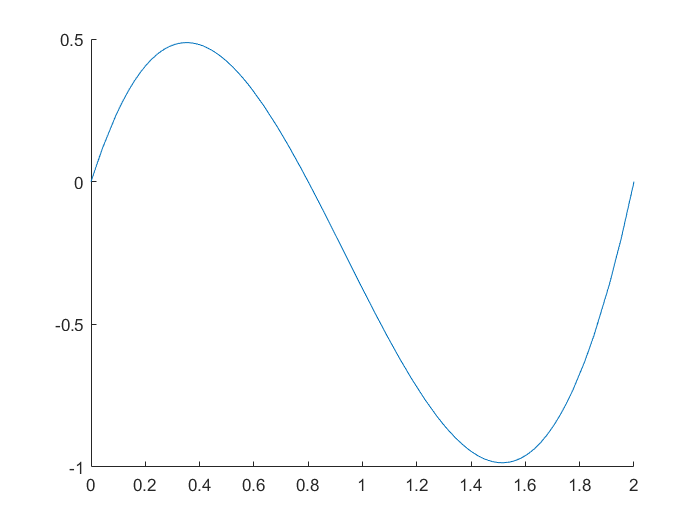

fplot(func, [0,T])
hold off 


%velocity
clf
hold on
fprintf("velocity")

velocity

func = subs(q_t_dot_1)

$$func = \frac{15\,t^{4}}{32}-\frac{7\,t^{3}}{4}+\frac{3\,t^{2}}{2}+\frac{1}{2}$$

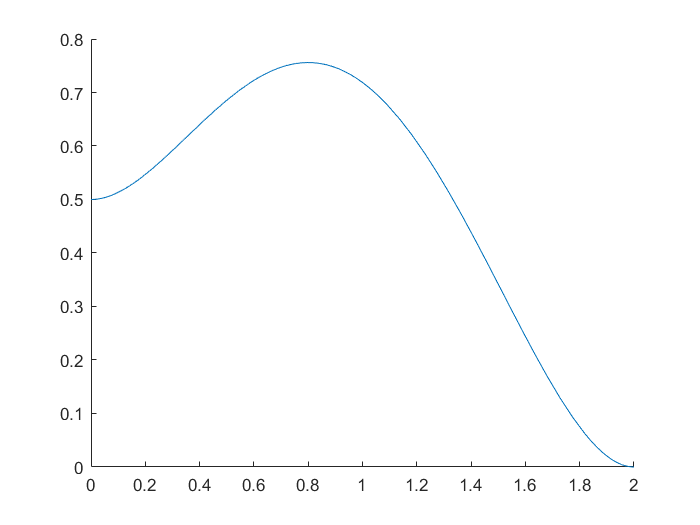

fplot(func, [0,T])
hold off 


%position
clf
hold on
fprintf("position")

position

func = subs(q_t_1)

$$func = \frac{3\,t^{5}}{32}-\frac{7\,t^{4}}{16}+\frac{t^{3}}{2}+\frac{t}{2}$$

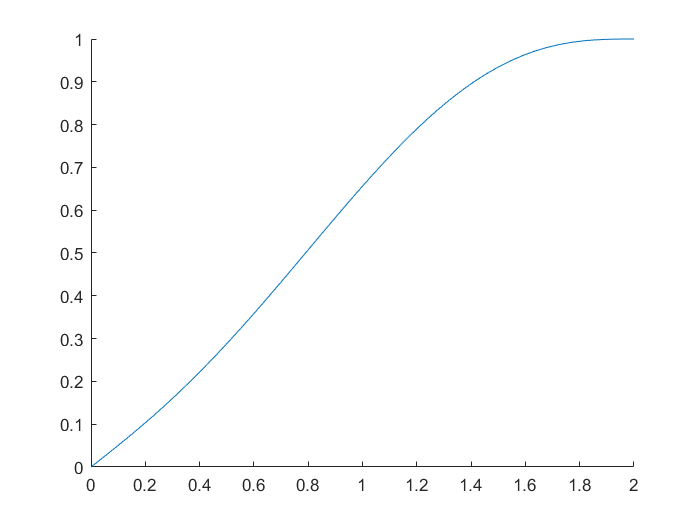

fplot(func, [0,T])
hold off 

fprintf("#########################################################")

#########################################################

% put s(tau) in r(s)
syms s(t) real positive 

A = [5.2 1.5]'

A =     5.2000
    1.5000


B = [2.2 -2.5]'

B =     2.2000
   -2.5000


p = A + s*(B-A)

$$p = \left(\begin{array}{c} \frac{26}{5}-3\,s\\ \frac{3}{2}-4\,s \end{array}\right)$$

p_dot = (B)
sigma = atan2(4, 3);
gamma_a = sigma + 90 - 60

gamma_a = 30.9273

gamma_b = sigma + 90 + 30

gamma_b = 120.9273


gamma = simplify(gamma_a + s*(gamma_b-gamma_a))

$$gamma = 90\,s+\frac{2176314925302647}{70368744177664}$$


%plot 
s = 

syms q1 real
syms q2 real
syms q3 real 

syms l real positive

alpha = [pi/2 pi/2 0];
a=[0 0 l];
d=[0 q2 0];
theta=[q1+pi/2 pi q3+pi/2];

table=[alpha',a',d',theta']

[T, A] = DHMatrix(table);
A0_1=A{1}
A1_2=A{2}
A2_3=A{3}

T
% how to obtain f_r, (i.e. r)
%{
    From DH table:
        A0_2 = A0_1 * A1_2 //mapping from frame 2 to frame 0
    So, to obtain the origin of frame 2 in frame 0:
        O2_2 = [0 0 0] % 3D space
            -> O2_2_H = [0 0 0 1] //homog. transf
        
        r = O0_2 = [rx ry rz 1]' = A0_2*O2_2_H 
%}
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2); f_r_3D(4)]